% Expand Fourier series of periodic functions f(x) with period T, 
% given on the indicated intervals:
% f(x)=cos(2*x); T=2*pi; [0;pi]
% Expand in a seris by sines.

clear
pi1=pi;
syms x real;
syms pi;
f(x)=piecewise(-pi<=x<0,-cos(2*x),0<x<=pi,cos(2*x))

$$f(x) = \left\{ \begin{array}{cl} -\cos\left(2\,x\right) & \text{ if }x\in \left[-\pi ,0\right)\\ \cos\left(2\,x\right) & \text{ if }x\in \left(0,\pi \right] \end{array}\right.$$


syms m integer;
[a0,a(m),b(m),abf(m)]=fourierseries(f)

$$a0 = 0$$

$$a(m) = 0$$

$$b(m) = \left\{ \begin{array}{cl} 0 & \text{ if }m\in \left\{-2,2\right\}\\ -\frac{2\,m\,\left({\left(-1\right)}^{m}-1\right)}{\pi \,\left(m^{2}-4\right)} & \text{ if }m\neq -2\wedge m\neq 2 \end{array}\right.$$

$$abf(m) = \left\{ \begin{array}{cl} 0 & \text{ if }m\in \left\{-2,2\right\}\\ -\frac{2\,m\,\sin\left(m\,x\right)\,\left({\left(-1\right)}^{m}-1\right)}{\pi \,\left(m^{2}-4\right)} & \text{ if }m\neq -2\wedge m\neq 2 \end{array}\right.$$

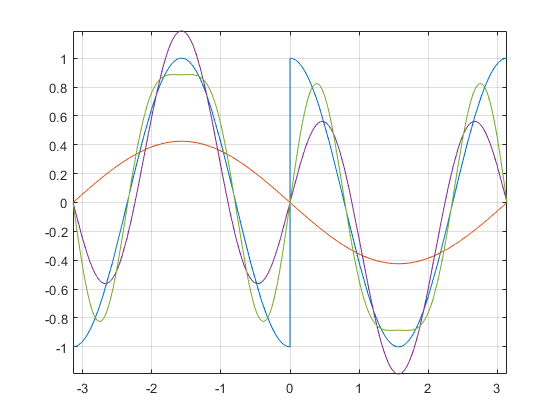


fplot(f(x),[-pi1 pi1]);
grid on
hold on

f1=a0/2;
for m=1:5
    if m==2
        m1(m)=m;
        continue;
    end
    m1(m)=m;
    a1(m)=a(m);
    b1(m)=b(m);
    abf1(m)=abf(m);
    f1=f1+abf(m);
    fplot(f1,[-pi1 pi1])
    grid on
end
hold off


a0/2

$$ans = 0$$

% 0
ft=[m1;a1;b1;abf1];
ft'

$$ans = \left(\begin{array}{cccc} 1 & 0 & -\frac{4}{3\,\pi } & -\frac{4\,\sin\left(x\right)}{3\,\pi }\\ 2 & 0 & 0 & 0\\ 3 & 0 & \frac{12}{5\,\pi } & \frac{12\,\sin\left(3\,x\right)}{5\,\pi }\\ 4 & 0 & 0 & 0\\ 5 & 0 & \frac{20}{21\,\pi } & \frac{20\,\sin\left(5\,x\right)}{21\,\pi } \end{array}\right)$$

% [ 1, 0,  -4/(3*pi),    -(4*sin(x))/(3*pi)]
% [ 2, 0,          0,                     0]
% [ 3, 0,  12/(5*pi),  (12*sin(3*x))/(5*pi)]
% [ 4, 0,          0,                     0]
% [ 5, 0, 20/(21*pi), (20*sin(5*x))/(21*pi)]